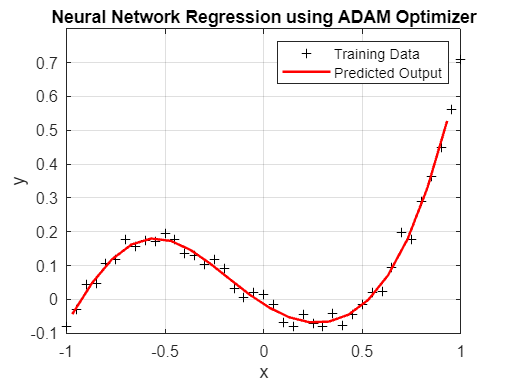

clear;
clc;

%% Training data input x
x = -1:0.05:1;
len = length(x);

%% Training data output y, with added noise
d = 0.8*x.^3 + 0.3*x.^2 - 0.4*x + normrnd(0, 0.02, [1, len]);

%% Network Parameters
learning_rate = 0.001;
epochs = 10000;
phi_hidden = @(x) tanh(x); % Activation function for hidden layer
phi_hidden_derivative = @(x) 1 - tanh(x).^2; % Derivative of tanh
delta_cost_output = @(error, hidden_out) -error * hidden_out;
delta_cost_hidden = @(error, weight, derivative, input) -error * weight * derivative * input;
epsilon = 1e-5;
beta1 = 0.9;
beta2 = 0.999;

%% Weights & Bias Initialization
w_1 = [randn * 0.1, randn * 0.1, randn * 0.1];
w_2 = [randn * 0.1, randn * 0.1, randn * 0.1];
xb = [randn * 0.1, randn * 0.1, randn * 0.1, randn * 0.1]; % Biases for hidden and output layer, initialized with small values

%% Initialize moment estimates for ADAM
m_w1 = [0, 0, 0];
m_w2 = [0, 0, 0];
m_xb = [0, 0, 0, 0];

v_w1 = [0, 0, 0];
v_w2 = [0, 0, 0];
v_xb = [0, 0, 0, 0];

v_1 = [0, 0, 0];
hidden_output = [0, 0, 0];
grad_w_1 = [0, 0, 0];
grad_w_2 = [0, 0, 0];
grad_xb = [0, 0, 0, 0];

% Training the neural network using ADAM
for epoch = 1:epochs
    for i = 1:len
        % Forward Propagation
        input = x(i);
        desired = d(i);

        % Hidden Layer Calculations
        for j = 1: length(v_1)
            v_1(j) = (w_1(j) * input) + xb(j+1);
            hidden_output(j) = phi_hidden(v_1(j));
        end

        % Output Layer Calculations
        v_2_1 = (w_2(1) * hidden_output(1)) + (w_2(2) * hidden_output(2)) + (w_2(3) * hidden_output(3)) + xb(1);
        % Error Calculation
        error = desired - v_2_1; % Linear activation function at output

        % ADAM Update for each parameter
        for j = 1:length(grad_w_2)
            grad_w_2(j) = delta_cost_output(error, hidden_output(j));
            m_w2(j) = (beta1 * m_w2(j)) + ((1 - beta1) * grad_w_2(j));
            v_w2(j) = (beta2 * v_w2(j)) + ((1 - beta2) * (grad_w_2(j) ^ 2));
            w_2(j) = w_2(j) - (learning_rate * ((m_w2(j) / (1 - beta1^epoch)) / (sqrt((v_w2(j) / (1 - beta2^epoch)) + epsilon))));
        end
        for j = 1:length(grad_w_1)
            grad_w_1(j) = delta_cost_hidden(error, w_2(j), phi_hidden_derivative(v_1(j)), input);
            m_w1(j) = (beta1 * m_w1(j)) + ((1 - beta1) * grad_w_1(j));
            v_w1(j) = beta2 * v_w1(j) + ((1 - beta2) * (grad_w_1(j) ^ 2));
            w_1(j) = w_1(j) - (learning_rate * ((m_w1(j) / (1 - beta1^epoch)) / (sqrt((v_w1(j) / (1 - beta2^epoch)) + epsilon))));
        end

        grad_xb(1) = -error;
        m_xb(1) = (beta1 * m_xb(1)) + ((1 - beta1) * grad_xb(1));
        v_xb(1) = beta2 * v_xb(1) + ((1 - beta2) * (grad_xb(1) ^ 2));
        xb(1) = xb(1) - (learning_rate * ((m_xb(1) / (1 - beta1^epoch)) / (sqrt((v_xb(1) / (1 - beta1^epoch)) + epsilon))));
        for j = 2:4 
            grad_xb(j) = delta_cost_hidden(error, w_2(j-1), phi_hidden_derivative(v_1(j-1)), 1);
            m_xb(j) = (beta1 * m_xb(j)) + ((1 - beta1) * grad_xb(j));
            v_xb(j) = beta2 * v_xb(j) + ((1 - beta2) * (grad_xb(j) ^ 2));
            xb(j) = xb(j) - (learning_rate * ((m_xb(j) / (1 - beta1^epoch)) / (sqrt((v_xb(j) / (1 - beta1^epoch)) + epsilon))));
        end
    end
end

% Prediction on test data
x_test = -0.97:0.1:0.93;
y_pred = zeros(size(x_test));

for i = 1:length(x_test)
    input = x_test(i);

    % Hidden Layer Calculations
    for j = 1:3
        v_1(j) = (w_1(j) * input) + xb(j+1);
        hidden_output(j) = phi_hidden(v_1(j));
    end
    % Output Layer Calculations
    v_1_2 = (w_2(1) * hidden_output(1)) + (w_2(2) * hidden_output(2)) + (w_2(3) * hidden_output(3)) + xb(1);
    y_pred(i) = v_1_2; % Linear activation function at output
end

% Plotting the results
figure;
plot(x, d, 'k+', 'DisplayName', 'Training Data');
hold on;
plot(x_test, y_pred, 'r-', 'LineWidth', 1.5, 'DisplayName', 'Predicted Output');
xlabel('x');
ylabel('y');
legend;
title('Neural Network Regression using ADAM Optimizer');
grid on;